chimp = getgenbank('NC_001643');
chimpSeq = chimp.Sequence;

bases=basecount(chimpSeq)

bases = struct with fields:
    A: 5154
    C: 5099
    G: 2133
    T: 4168


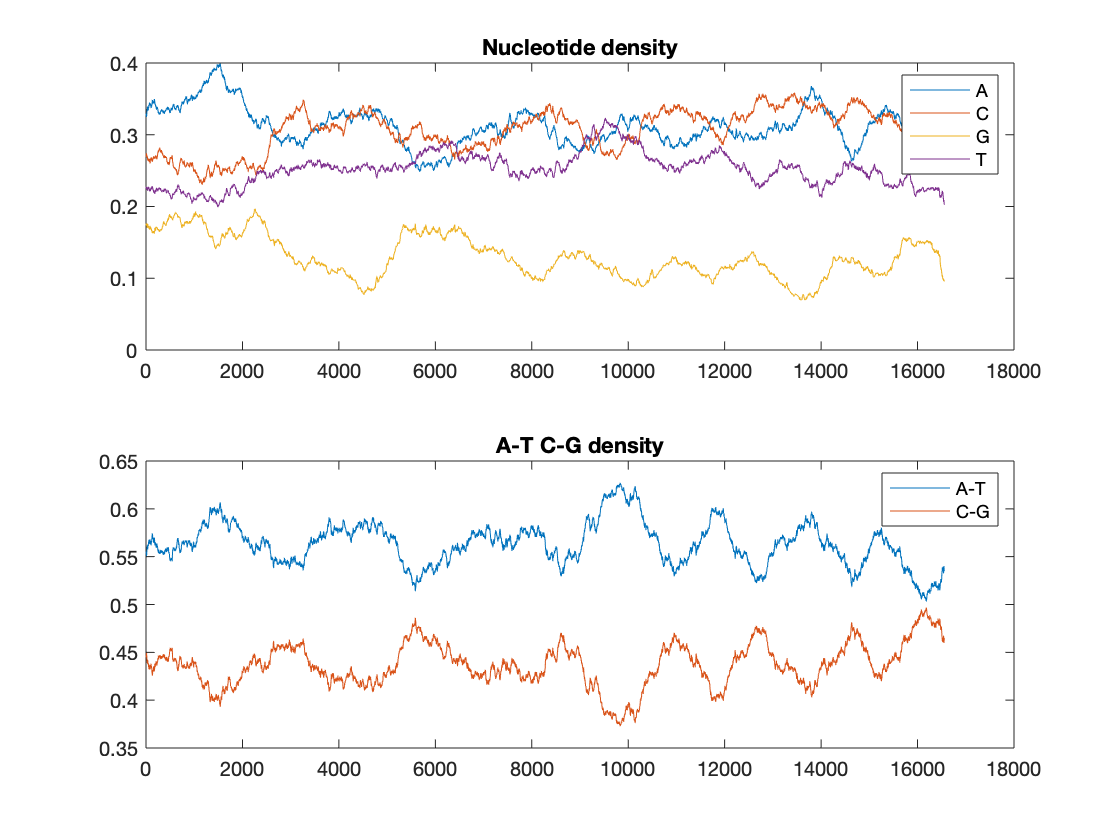

ntdensity(chimpSeq)

gene_coding_seq = chimp.CDS

gene_coding_seq = 1×13 struct array with fields:
    location
    gene
    product
    codon_start
    indices
    protein_id
    db_xref
    note
    translation
    text


seqs = []


seqs =

     []



cytb_seqs = [];
for i=1:length(gene_coding_seq)
    if strcmp(gene_coding_seq(i).gene, 'CYTB')
        orfStart = gene_coding_seq(i).indices(1,1);
        orfEnd =  gene_coding_seq(i).indices(1,2);
        cytb_seqs = [cytb_seqs; chimpSeq(orfStart:orfEnd)];
    end
end
cytb_seqs

cytb_seqs = 'atgaccccgacacgcaaaattaacccactaataaaattaattaatcactcatttatcgacctccccaccccatccaacatttccgcatgatggaacttcggctcacttctcggcgcctgcctaatccttcaaattaccacaggattattcctagctatacactactcaccagacgcctcaaccgccttctcgtcgatcgcccacatcacccgagacgtaaactatggttggatcatccgctacctccacgctaacggcgcctcaatattttttatctgcctcttcctacacatcggccgaggtctatattacggctcatttctctacctagaaacctgaaacattggcattatcctcttgctcacaaccatagcaacagcctttatgggctatgtcctcccatgaggccaaatatccttctgaggagccacagtaattacaaacctactgtccgctatcccatacatcggaacagacctggtccagtgagtctgaggaggctactcagtagacagccctacccttacacgattcttcaccttccactttatcttacccttcatcatcacagccctaacaacacttcatctcctattcttacacgaaacaggatcaaataaccccctaggaatcacctcccactccgacaaaattaccttccacccctactacacaatcaaagatatccttggcttattccttttcctccttatcctaatgacattaacactattctcaccaggcctcctaggcgatccagacaactataccctagctaaccccctaaacaccccaccccacattaaacccgagtgatactttctatttgcctacacaatcctccgatccatccccaacaaactaggaggcgtcctcgccctactactatctatcctaatcctaacagcaatccctgtcctccacacatccaaacaacaaagcataatatttcgcccactaagccaactgctttactgactcctagcc

bases=basecount(cytb_seqs)

bases = struct with fields:
    A: 330
    C: 391
    G: 134
    T: 286


genome_id = sprintf('%s ',gene_coding_seq.gene)

genome_id = 'ND1 ND2 COX1 COX2 ATP8 ATP6 COX3 ND3 ND4L ND4 ND5 ND6 CYTB '

cytb = chimp.CDS(13)

cytb = struct with fields:
       location: '14165..15305'
           gene: 'CYTB'
        product: 'cytochrome b'
    codon_start: '1'
        indices: [14165 15305]
     protein_id: 'NP_008198.1'
        db_xref: 'GeneID:807858'
           note: [2×51 char]
    translation: 'MTPTRKINPLMKLINHSFIDLPTPSNISAWWNFGSLLGACLILQITTGLFLAMHYSPDASTAFSSIAHITRDVNYGWIIRYLHANGASMFFICLFLHIGRGLYYGSFLYLETWNIGIILLLTTMATAFMGYVLPWGQMSFWGATVITNLLSAIPYIGTDLVQWVWGGYSVDSPTLTRFFTFHFILPFIITALTTLHLLFLHETGSNNPLGITSHSDKITFHPYYTIKDILGLFLFLLILMTLTLFSPGLLGDPDNYTLANPLNTPPHIKPEWYFLFAYTILRSIPNKLGGVLALLLSILILTAIPVLHTSKQQSMMFRPLSQLLYWLLATDLLILTWIGGQPVSYPFITIGQMASVLYFTTILILMPIASLIENKMLEWT'
           text: [17×58 char]


orfStart = cytb.indices(1,1)

orfStart = 14165

orfEnd = cytb.indices(1,2)

orfEnd = 15305

cytb_seq = chimpSeq(orfStart:orfEnd)

cytb_seq = 'atgaccccgacacgcaaaattaacccactaataaaattaattaatcactcatttatcgacctccccaccccatccaacatttccgcatgatggaacttcggctcacttctcggcgcctgcctaatccttcaaattaccacaggattattcctagctatacactactcaccagacgcctcaaccgccttctcgtcgatcgcccacatcacccgagacgtaaactatggttggatcatccgctacctccacgctaacggcgcctcaatattttttatctgcctcttcctacacatcggccgaggtctatattacggctcatttctctacctagaaacctgaaacattggcattatcctcttgctcacaaccatagcaacagcctttatgggctatgtcctcccatgaggccaaatatccttctgaggagccacagtaattacaaacctactgtccgctatcccatacatcggaacagacctggtccagtgagtctgaggaggctactcagtagacagccctacccttacacgattcttcaccttccactttatcttacccttcatcatcacagccctaacaacacttcatctcctattcttacacgaaacaggatcaaataaccccctaggaatcacctcccactccgacaaaattaccttccacccctactacacaatcaaagatatccttggcttattccttttcctccttatcctaatgacattaacactattctcaccaggcctcctaggcgatccagacaactataccctagctaaccccctaaacaccccaccccacattaaacccgagtgatactttctatttgcctacacaatcctccgatccatccccaacaaactaggaggcgtcctcgccctactactatctatcctaatcctaacagcaatccctgtcctccacacatccaaacaacaaagcataatatttcgcccactaagccaactgctttactgactcctagcca

cytb_aminoacid = nt2aa(cytb_seq, 'geneticcode',2)

cytb_aminoacid = 'MTPTRKINPLMKLINHSFIDLPTPSNISAWWNFGSLLGACLILQITTGLFLAMHYSPDASTAFSSIAHITRDVNYGWIIRYLHANGASMFFICLFLHIGRGLYYGSFLYLETWNIGIILLLTTMATAFMGYVLPWGQMSFWGATVITNLLSAIPYIGTDLVQWVWGGYSVDSPTLTRFFTFHFILPFIITALTTLHLLFLHETGSNNPLGITSHSDKITFHPYYTIKDILGLFLFLLILMTLTLFSPGLLGDPDNYTLANPLNTPPHIKPEWYFLFAYTILRSIPNKLGGVLALLLSILILTAIPVLHTSKQQSMMFRPLSQLLYWLLATDLLILTWIGGQPVSYPFITIGQMASVLYFTTILILMPIASLIENKMLEWT'

cytb_aminoacid(1:50)

ans = 'MTPTRKINPLMKLINHSFIDLPTPSNISAWWNFGSLLGACLILQITTGLF'

length(cytb_aminoacid)

ans = 380

cox1 = chimp.CDS(3);

cox1_seq = chimpSeq(cox1.indices(1,1):cox1.indices(1,2))

cox1_seq = 'atgttcaccgaccgctgactattctctacaaaccacaaagatattggaacactatacctactattcggtgcatgagctggagtcctgggcacagccctaagtctccttattcgggctgaactaggccaaccaggcaacctcctaggtaatgaccacatctacaatgtcatcgtcacagcccatgcattcgtaataatcttcttcatagtaatgcctattataatcggaggctttggcaactggctagttcccttgataattggtgcccccgacatggcattcccccgcataaacaacataagcttctggctcctgcccccttctctcctacttctacttgcatctgccatagtagaagccggcgcgggaacaggttgaacagtctaccctcccttagcgggaaactactcgcatcctggagcctccgtagacctaaccatcttctccttacatctggcaggcatctcctctatcctaggagccattaacttcatcacaacaattattaatataaaacctcctgccatgacccaataccaaacacccctcttcgtctgatccgtcctaatcacagcagtcttacttctcctatccctcccagtcctagctgctggcatcaccatactattgacagatcgtaacctcaacactaccttcttcgacccagccgggggaggagaccctattctatatcaacacttattctgattttttggccaccccgaagtttatattcttatcctaccaggcttcggaataatttcccacattgtaacttattactccggaaaaaaagaaccatttggatatataggcatggtttgagctataatatcaattggcttcctagggtttatcgtgtgagcacaccatatatttacagtagggatagacgtagacacccgagcctatttcacctccgctaccataatcattgctattcctaccggcgtcaaagtattcagctgactcgctacacttcacggaa

cox1_aminoacid = nt2aa(cox1_seq,'geneticcode',2)

cox1_aminoacid = 'MFTDRWLFSTNHKDIGTLYLLFGAWAGVLGTALSLLIRAELGQPGNLLGNDHIYNVIVTAHAFVMIFFMVMPIMIGGFGNWLVPLMIGAPDMAFPRMNNMSFWLLPPSLLLLLASAMVEAGAGTGWTVYPPLAGNYSHPGASVDLTIFSLHLAGISSILGAINFITTIINMKPPAMTQYQTPLFVWSVLITAVLLLLSLPVLAAGITMLLTDRNLNTTFFDPAGGGDPILYQHLFWFFGHPEVYILILPGFGMISHIVTYYSGKKEPFGYMGMVWAMMSIGFLGFIVWAHHMFTVGMDVDTRAYFTSATMIIAIPTGVKVFSWLATLHGSNMKWSAAVLWALGFIFLFTVGGLTGIVLANSSLDIVLHDTYYVVAHFHYVLSMGAVFAIMGGFIHWFPLFSGYTLDQTYAKIQFAIMFIGVNLTFFPQHFLGLSGMPRRYSDYPDAYTTWNVLSSVGSFISLTAVMLMIFMIWEAFASKRKVLMVEEPSANLEWLYGCPPPYHTFEEPVYMKS*'

length(cox1_seq)

ans = 1542

basecount(cox1_seq)

ans = struct with fields:
    A: 413
    C: 453
    G: 256
    T: 420


length(cox1_aminoacid)

ans = 514

cox1_aminoacid(1:50)

ans = 'MFTDRWLFSTNHKDIGTLYLLFGAWAGVLGTALSLLIRAELGQPGNLLGN'

Collecting few primates in a table to compare their cytb proteins and make a tree

data = {'Pan troglodytes'   'NP_008198';
        'Pan paniscus' 'ADA55535';
        'Homo sapiens' 'AFI52643';
        'Gorilla gorilla gorilla' 'AMB65506';
        'Pongo abelii' 'AMB65558';
        'Papio cynocephalus' 'AFX82173';
        'Pan troglodytes verus' 'ACY65608';
        'Pan troglodytes ellioti' 'AMB65389'};

NumCytb=length(data);

for ind = 1:NumCytb
    cytb_data(ind).Header   = data{ind,1};
    cytb_data(ind).Sequence = getgenpept(data{ind,2},'sequenceonly','true');
end

distances = seqpdist(cytb_data,'method','jukes-cantor','indels','pairwise-delete','squareform',true)

NJtree = seqneighjoin(distances,'equivar',cytb_data);
h = plot(NJtree,'orient','left');
title('Neighbor-joining tree using Jukes-Cantor model');

tree1=reroot(NJtree,8);
title('Neighbor-joining tree using Jukes-Cantor model');
view(tree1)

phytreeviewer(tree1)

Get the accession number for the sequences of all